# Home Ground Advantage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

resultsAndGoals = readtable("../data/results.csv")

resultsAndGoals = 20×11 table
    homeWins    homeLosses    awayWins    awayLosses              Team              homeDraws    awayDraws    homeGF    homeGA    awayGF    awayGA
    ________    __________    ________    __________    ________________________    _________    _________    ______    ______    ______    ______

       12            1           11            2        {'Leicester City'      }        6            6          35        18        33        18  
       12            3            8            4        {'Arsenal'             }        4            7          31        11        34        25  
       

homeGF = resultsAndGoals.homeGF;
homeGA = resultsAndGoals.homeGA;
awayGF = resultsAndGoals.awayGF;
awayGA = resultsAndGoals.awayGA;
homeWins = resultsAndGoals.homeWins;
awayWins = resultsAndGoals.awayWins;

whos

  Name                  Size            Bytes  Class     Attributes

  awayGA               20x1               160  double              
  awayGF               20x1               160  double              
  awayWins             20x1               160  double              
  homeGA               20x1               160  double              
  homeGF               20x1               160  double              
  homeWins             20x1               160  double              
  resultsAndGoals      20x11             7383  table               



## Task 1

GDH = homeGF - homeGA;
GDA = awayGF - awayGA;

## Task 2

moreHomeWins = homeWins > awayWins;

scatter(GDH(moreHomeWins), GDA(moreHomeWins))
grid minor
hold on
scatter(GDH(~moreHomeWins), GDA(~moreHomeWins))
hold off

**Do not edit.** This code annotates the plot and adds the diagonal line.

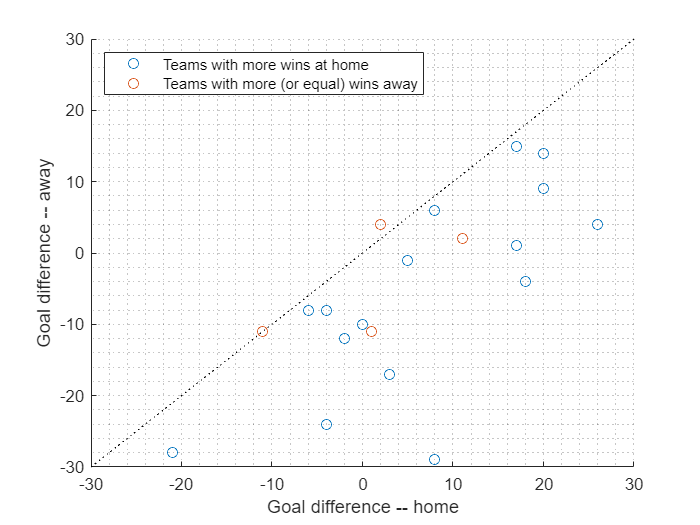

xlabel("Goal difference -- home")
ylabel("Goal difference -- away")
legend("Teams with more wins at home","Teams with more (or equal) wins away", "AutoUpdate", "off", "Location", "northwest")
hold on
plot([-30 30], [-30 30], "k:")
hold off